Vehicle Control Engineering: Homework 5

Author: Huiqian LI

Date: 2020.12.30

clear,clc
global gridN
global Ap
global Bp 
global Qp
global Rp
gridN = 200;
Ap = -1;
Bp = 1;
Qp = 1;
Rp = 1;
% (3)
Solve_OCP

Bp = 1

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         402    1.774688e+03     3.900e+02     1.000e+00     0.000e+00     1.000e+01  
    1         804    2.306187e+03     9.553e-11     1.000e+00     7.100e+01     9.637e+00  
    2        1206    1.680536e+03     7.218e-12     1.000e+00     3.373e+01     3.454e+00  
    3        1608    1.620229e+03     2.206e-12     1.000e+00     7.916e+00     1.340e-01  
    4        2010    1.620218e+03     4.974e-14     1.000e+00     1.510e-01     7.133e-03  
    5        2412    1.620218e+03     3.197e-14     1.000e+00     1.512e-02     1.657e-03  
    6        2814    1.620218e+03     4.263e-14     1.000e+00     6.713e-03     9.979e-04  
    7        3216    1.620218e+03     3.020e-14     1.000e+00     1.024e-03     1.110e-04  
    8        3230    1.620218e+03     3.020e-14     6.782e-03     8.321e-07     1.

Bp = 0.1000

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         402    1.774688e+03     3.900e+02     1.000e+00     0.000e+00     1.000e+01  
    1         804    2.050015e+03     1.847e-10     1.000e+00     5.667e+01     9.749e+00  
    2        1206    2.034960e+03     3.597e-13     1.000e+00     1.315e+01     1.753e+00  
    3        1608    1.998915e+03     1.830e-13     1.000e+00     6.021e+00     8.201e-02  
    4        2010    1.998908e+03     6.217e-14     1.000e+00     1.227e-01     4.164e-03  
    5        2412    1.998908e+03     6.040e-14     1.000e+00     1.203e-02     1.553e-03  
    6        2814    1.998908e+03     4.619e-14     1.000e+00     5.032e-03     1.079e-03  
    7        3216    1.998908e+03     5.684e-14     1.000e+00     1.362e-03     1.666e-04  
    8        3228    1.998908e+03     5.684e-14     1.384e-02     2.222e-06     1.

Bp = 10

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         402    1.774688e+03     3.900e+02     1.000e+00     0.000e+00     1.000e+01  
    1         804    1.915465e+03     1.392e-10     1.000e+00     8.265e+01     9.200e+00  
    2        1206    3.148280e+02     7.282e-11     1.000e+00     4.100e+01     2.953e+00  
    3        1608    3.082899e+02     3.391e-11     1.000e+00     3.951e+00     6.178e-01  
    4        2010    3.079552e+02     6.082e-12     1.000e+00     7.403e-01     1.767e-02  
    5        2413    3.079552e+02     1.933e-12     7.000e-01     2.697e-02     9.538e-03  
    6        2815    3.079550e+02     2.842e-14     1.000e+00     1.530e-02     3.894e-03  
    7        3220    3.079550e+02     7.105e-15     3.430e-01     6.473e-03     3.599e-03  
    8        3625    3.079550e+02     2.842e-14     3.430e-01     3.945e-03     3.

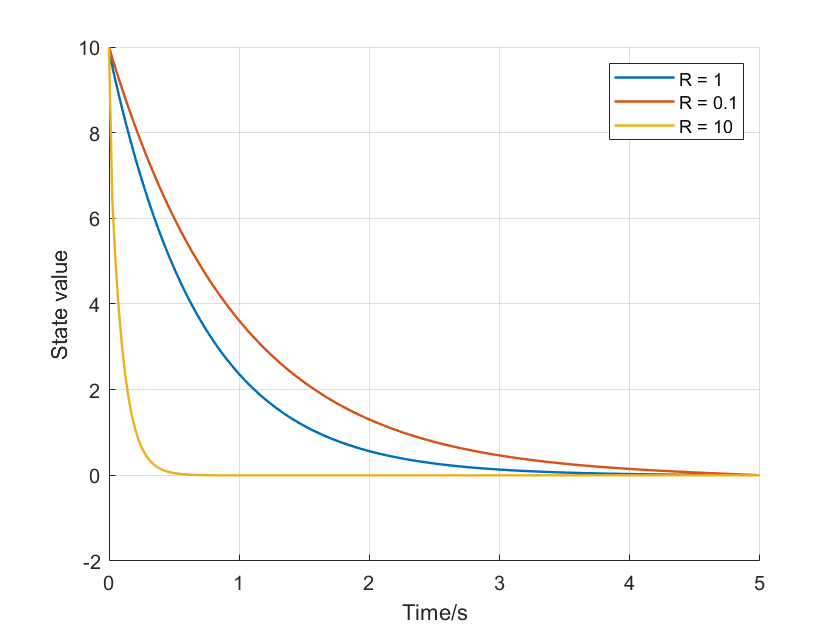

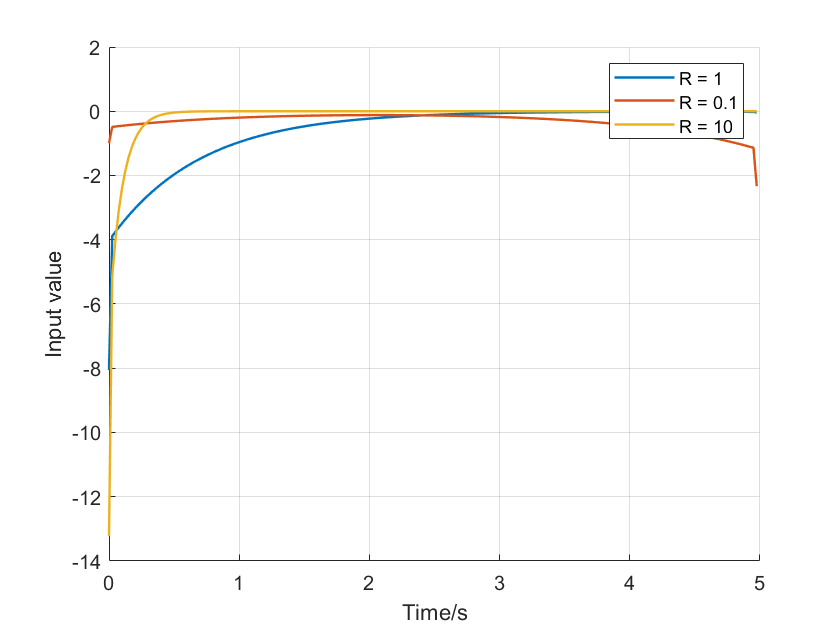

% (4)
figure(1)

hold on
figure(2)
hold on
Aps = [-1,-0.1,-10];
Bps = [1,0.1,10];
Qps = [1,0.1,10];
Rps = [1,0.1,10];
for i = 1:3
    Bp = Bps(i)
    Solve_OCP
end
figure(1)
hold off
legend("R = 1","R = 0.1","R = 10")
figure(2)
hold off
legend("R = 1","R = 0.1","R = 10")
